## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

This model for complex formation (4 species) is already implemented with the name as `BIOMD0000000009-matlab` and `func_huang96_biomod_p1` and `func_huang96_biomod_p2`, provided respectively by BioModels and Prof. Baum, saved in the path for models as above.

In case there is any fixes, new code will be implemented below:

Parameters:

% Parameters from supplementary material
x0=zeros(26,1);
x0(1) = 3.0E-5;
x0(2) = 3.0E-4;
x0(3) = 0.003;
x0(4) = 0.0;
x0(5) = 1.2;
x0(6) = 0.0;
x0(7) = 0.0;
x0(8) = 1.2;
x0(9) = 0.0;
x0(10) = 0.0;
x0(11) = 0.12;
x0(12) = 3.0E-4;
x0(13) = 0.0;
x0(14) = 0.0;
x0(15) = 0.0;
x0(16) = 0.0;
x0(17) = 0.0;
x0(18) = 0.0;
x0(19) = 0.0;
x0(20) = 0.0;
x0(21) = 0.0;
x0(22) = 0.0;
x0(23) = 0;
x0(24) = 0;
x0(25) = 0;
x0(26) = 0;

s_star = x0';  % Initial concentrations

## 2. Result reproduction

### Temporal dynamics

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 5000, 1001);
t_perb = 0.2 % where pertubation happens

t_perb = 0.2000

opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_huang96_biomod_p2(t,x), tspan, x0, opts);
s_star_2=sol(end,:); %the last point of the simulation is chosen

Plot

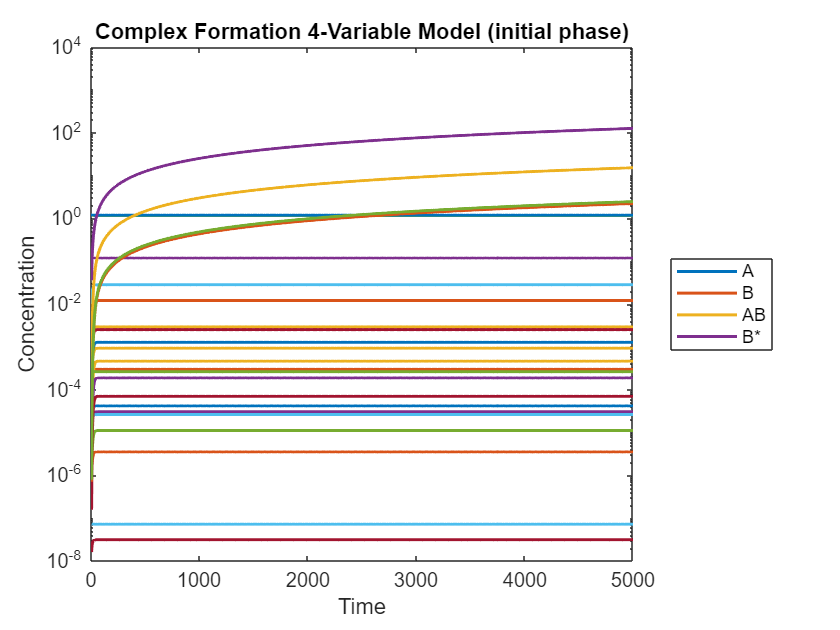

figure;
semilogy(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,5000]);
title('Complex Formation 4-Variable Model (initial phase)');
legend('A','B','AB','B*','Location','eastoutside'); % southeast

QC block:

y0 = s_star_2(:);

f_un = func_varusai15_s4_fix(0, y0);

Unrecognized function or variable 'klin'.

f_st = func_varusai15_s4_fix(0, y0, klin, knonlin_stimulated);

disp([f_un f_st f_st - f_un])   % columns: unstim, stim, difference
disp(norm(f_st - f_un))

Now, draw temporal dynamics for unstimulated conditions from t=[-1000, 0], and then stimulated conditions from t=[0, 2000].

tspan_1 = linspace(-1000, 0, 500);
tspan_2 = linspace(0, 2000, 1000);
[t_un, sol_unstimulated] = ode15s(@(t,x) func_varusai15_s4_fix(t,x,klin, knonlin_unstimulated), tspan_1, s_star_2, opts);
[t_sti, sol_stimulated] = ode15s(@(t,x) func_varusai15_s4_fix(t,x,klin, knonlin_stimulated), tspan_2, sol_unstimulated(end,:), opts);

t_all = [t_un; t_sti(1:end)];
sol_all = [sol_unstimulated; sol_stimulated(1:end,:)];

Plot

figure;
semilogy(t_all, sol_all, 'LineWidth', 1.5);
xline(0, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([-1000,2000]);
title('Complex Formation 4-Variable Model (initial phase)');
legend('A','B','AB','B*','Location','eastoutside'); % southeast

### **Detect loop structure change:**

j_0_un = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_unstimulated),s_star_2);
signed_j_0_un =sign(j_0_un)

j_0_sti = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_stimulated),sol_stimulated(end,:));
signed_j_0_sti =sign(j_0_sti)

for k = 1:numel(t_all)
    t = t_all(k);
    y = sol_all(k, :);  % 4x1 state at time t

    % choose params by time (stimulus at t=0)
    if t < 0
        knonlin_use = knonlin_unstimulated;
    else
        knonlin_use = knonlin_stimulated;
    end

    % Jacobian at this state
    j_matrix_t = numerical_jacobian_complex( ...
        @(x) func_varusai15_s4_fix(1, x, klin, knonlin_use), ...
        y);

    % signed Jacobian at this time
    signed_jacobian_t = sign(j_matrix_t);

    % Compare with baseline signed structure
    if ~isequal(signed_jacobian_t, signed_j_0_un)
        fprintf('At time %.2f after the stimulus, the signed Jacobian structure changes.\n', t);

        loop_list_t = find_loops(j_matrix_t);

        fprintf('Jacobian matrix at time %.2f:\n', t);
        disp(j_matrix_t);

        fprintf('Signed Jacobian matrix at time %.2f:\n', t);
        disp(signed_jacobian_t);

        fprintf('Loop summary at this time:\n');
        disp(loop_summary(loop_list_t));

        break
    end
end

### **Plot:**

colors = [
    0.5 0.5 0.5;   % gray
];

t_change = t;              % <-- the time when structure changes
tmin = t_all(1);
tmax = t_all(end);

figure;
ax = axes; hold(ax,'on');
xline(ax, t, '-', 'LineWidth', 1.5, 'Color', colors(1,:));

% set axes to log scale 
set(ax,'YScale','log');

% Plot your trajectories
h = semilogy(ax, t_all, sol_all, 'LineWidth', 1.5);

% Limits
xlim(ax, [-1000 2000]);
ylim(ax, [min(sol_all(:))*0.5, max(sol_all(:))*1.5]);  % or just ylim(ax,'auto')
yl = ylim(ax);

% shaded region BEFORE change (blue, alpha 0.1)
p1 = patch(ax, ...
    [tmin t_change t_change tmin], ...
    [yl(1) yl(1) yl(2) yl(2)], ...
    'b', 'FaceAlpha', 0.10, 'EdgeColor', 'none');

% shaded region AFTER change (red, alpha 0.1) ---
p2 = patch(ax, ...
    [t_change tmax tmax t_change], ...
    [yl(1) yl(1) yl(2) yl(2)], ...
    'r', 'FaceAlpha', 0.10, 'EdgeColor', 'none');

% Put patches behind the lines
uistack(p1,'bottom');
uistack(p2,'bottom');

% Vertical line at stimulus time (optional)
xline(ax, 0, '--', 'LineWidth', 1.5);

xlabel(ax,'Time');
ylabel(ax,'Concentration');
title(ax, ['Temporal Dynamics for Activation-Deactivation Cycle Model' newline ...
          'Unstimulated and Stimulated Conditions']);

legend(ax, {'Before','After','','A','B','AB','B*'}, 'Location','eastoutside');

### **Dynamics of B**

figure('Position',[100 100 400 300]);  % similar size to figsize=(4,3)

% Plot only B (column 2)
plot(t_all, sol_all(:,2), ...
     'LineWidth', 5, ...
     'Color', [0.85 0.33 0.10]);  

xlim([-999 2000]);

% Show only 0 and 2000 on x-axis
xticks([0 2000]);

% Match Python: np.arange(293,295,1)
yticks(293:1:294);

xlabel('Time');
ylabel('Concentration');
title('Dynamics of B');

box on

### **Loop structure:**

**Unstimulated condition:**

loop_list_un=find_loops_vset(@(x)func_varusai15_s4_fix(1,x,klin, knonlin_unstimulated),s_star_2',100); 
% max_num_loops does have effect in the final summary like in R
disp(loop_list_un{1})
disp(loop_summary(loop_list_un{1}))

**Stimulated condition:**

loop_list_sti=find_loops_vset(@(x)func_varusai15_s4_fix(1,x,klin, knonlin_stimulated),sol_stimulated(end,:)',100);
disp(loop_list_sti{1})
disp(loop_summary(loop_list_sti{1}))

### **Jacobian matrix:**

j_0_un = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_unstimulated),s_star_2);
signed_j_0_un =sign(j_0_un)

j_0_sti = numerical_jacobian_complex(@(x)func_varusai15_s4_fix(1, x, klin, knonlin_stimulated),sol_stimulated(end,:));
signed_j_0_sti =sign(j_0_sti)

## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_3_complex_formation_extend.mlx", "MATLAB/model_3_complex_formation_extend.pdf")
mdfile = export("MATLAB/model_3_complex_formation_extend.mlx","MATLAB/model_3_complex_formation_extend.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)